### Constant set up

        frame interval

        temperature

        probe radius

delta_t = 40; %frame interval in ms
temp_K = 303; %temperature in K
probe_radius = 12.5e-9; % in nm

Constants = struct(...
    'FrameInterval',     delta_t,...
    'Temperature',       temp_K,...
    'ProbeRadius',       probe_radius);

% Load results for viscosity calculation
UnpackResults(result_folder)


 All variables restored to workspace.


pop_nuc_ratio =...
    Pop_Nuc_Ratio(5e5,acc_fit,Ro,Lo,anchor_spMap,...
    scaling_width,scaling_length,num_pix_y,...
    aspt_ratio,nuc_contour{1});

[Step_in_Nuc,~] =...
    Extract_Step_InRegion(raw_spatialDisp,...
    coord_in_nuc,num_pix_y,aspt_ratio);

[Step_in_Nuc_simu,~] =...
    Extract_Step_InRegion(Simu_spatialDisp,...
    coord_in_nuc,num_pix_y,aspt_ratio);


### Nucleoid Viscosity

Data fitting (with Rayleigh distribution) to calculate nucleoid viscosity

pop_nuc_ratio

pop_nuc_ratio = 0.1212

slack_d=0.15        % diffusion coefficient +/- 15%

slack_d = 0.1500

slack_acc=0.075     % pop_nuc_ratio +/- slack

slack_acc = 0.0750

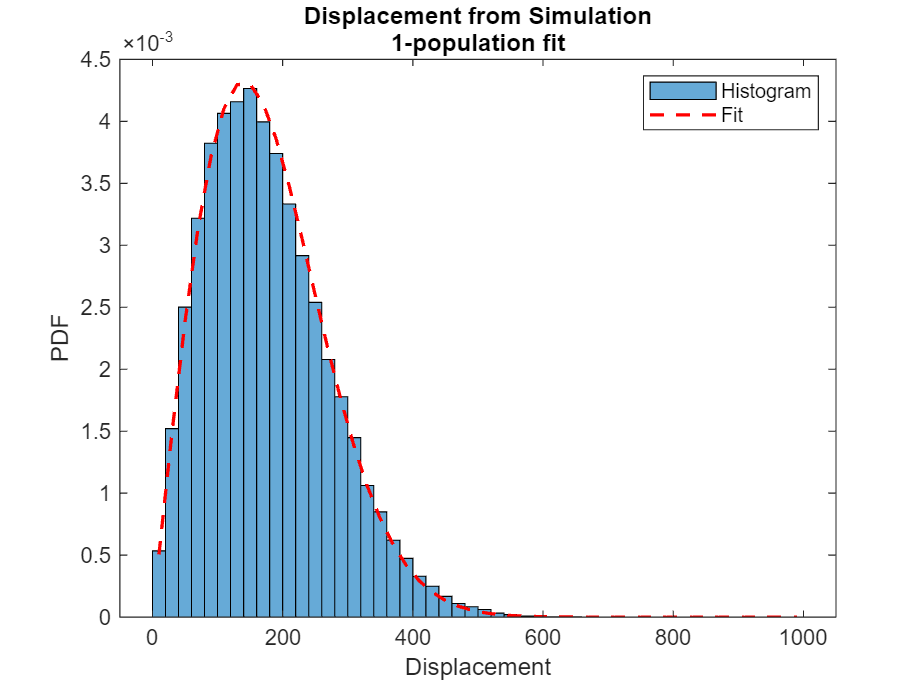


[p_simu,p_fit,simu_result,exp_result,f1,f2] =...
    In_Nuc_fit(Step_in_Nuc_simu,Step_in_Nuc,...
    pop_nuc_ratio,slack_d,slack_acc);

SaveFigure(result_folder,'Nucleoid fit from simulation',...
    f1, {'fig','png','svg'},[])

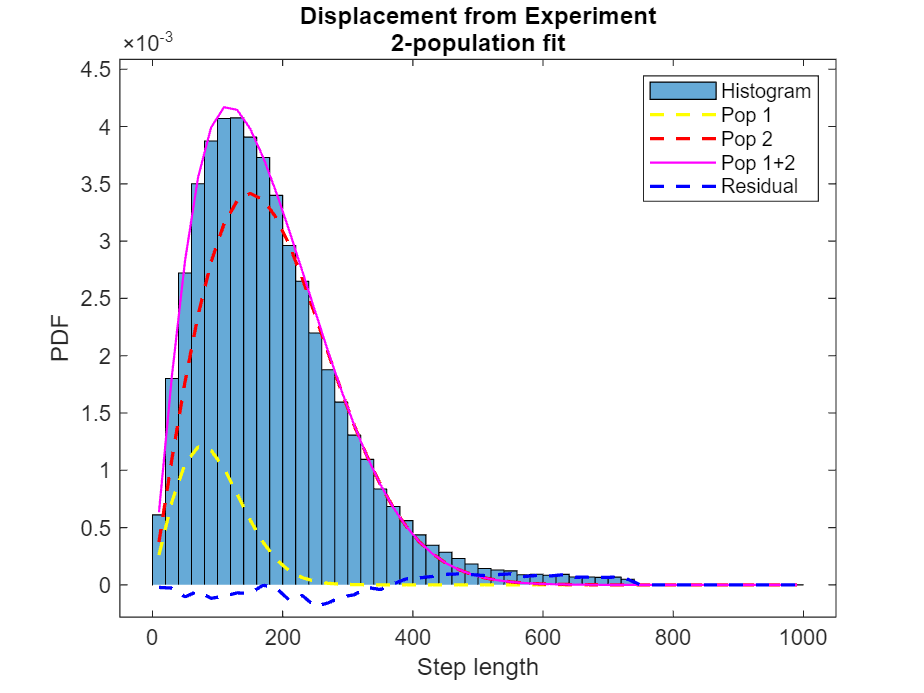

SaveFigure(result_folder,'Nucleoid fit from experiment',...
    f2, {'fig','png','svg'},[])

% compute error bar by nonlinear fitting parameter confidence interval
p_nuc_fit_ci = In_Nuc_fit_ci(Step_in_Nuc,p_fit);

%  Comparison with inputs / 1-population result
shift_nuc = struct( ...
    'InputNucRatio' , pop_nuc_ratio      , ...
    'FitNucRatio'   , p_fit(1)           , ...
    'delta_NucRatio', abs(p_fit(1)-pop_nuc_ratio) , ...
    'a_simulation'  , p_simu(1)          , ...
    'a_fit'         , p_fit(4)           , ...
    'delta_a_nuc'   , abs(p_fit(4)-p_simu(1))/p_simu(1));

% Physical properties derived from the fit
Diff_nuc_um2s = p_fit(2) / (4*delta_t) * 1e-3;            % µm²/s
Vis_nuc    = 1.380649e-23*temp_K / (6*pi*probe_radius* ...
                   Diff_nuc_um2s * 1e-12) * 1e3;          % cP
Vis_nuc_lb = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_nuc_fit_ci(2)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)
Vis_nuc_ub = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_nuc_fit_ci(1)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)

Viscosity_nuc = struct(...
    'NucRatio',        pop_nuc_ratio,...
    'Fitting_tolerance', [slack_d,slack_acc],...
    'DiffCoeff_um2_s', Diff_nuc_um2s,...
    'NucVis',          Vis_nuc,...
    'NucVis_lb',       Vis_nuc_lb,...
    'NucVis_ub',       Vis_nuc_ub);

fprintf('\n-----------  Physical Properties  -----------\n');


-----------  Physical Properties  -----------


fprintf('D_nuc  (µm²/s)           : %.3e\n', Diff_nuc_um2s);

D_nuc  (µm²/s)           : 7.261e-02


fprintf('Nucleoid Viscosity (cP)  : %.2f\n',   Vis_nuc);

Nucleoid Viscosity (cP)  : 244.52


fprintf('----------------------------------------------\n');

----------------------------------------------


### Cytoplasmic Viscosity

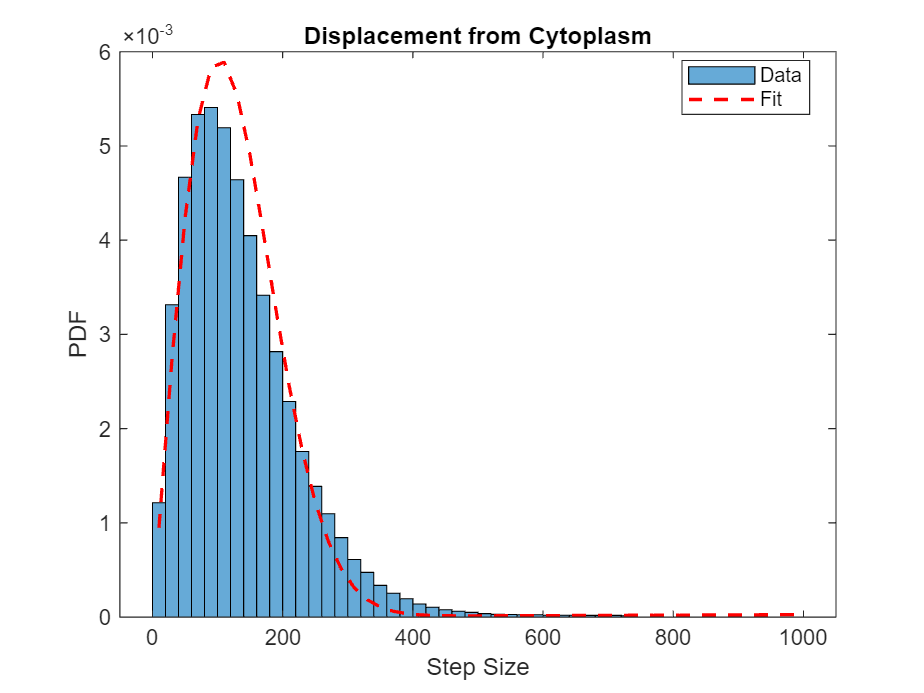

[p_cyto_fit,p_cyto_fit_ci,cyto_result] =...
    In_Cyto_fit(raw_spatialDisp,spMap,...
    coord_in_cyto,aspt_ratio,num_pix_y);
Diff_cyto = p_cyto_fit(1)/(4*delta_t)*1e-3;  % um^2/s
Diff_cyto_lb = p_cyto_fit_ci(1)/(4*delta_t)*1e-3; 
Diff_cyto_ub = p_cyto_fit_ci(2)/(4*delta_t)*1e-3;  
Vis_cyto = 1.380649e-23*temp_K/(6*pi*probe_radius*Diff_cyto*1e-12)*1e3; %cP (centipoise, mPa⋅s)
Vis_cyto_lb = 1.380649e-23*temp_K/(6*pi*probe_radius*Diff_cyto_ub*1e-12)*1e3; 
Vis_cyto_ub = 1.380649e-23*temp_K/(6*pi*probe_radius*Diff_cyto_lb*1e-12)*1e3;

SaveFigure(result_folder,'Cytoplasm fit',...
    gcf, {'fig','png','svg'},[])


Viscosity_cyto = struct(...
    'DiffCoeff_um2_s',  Diff_cyto,...
    'CytoVis',          Vis_cyto,...
    'CytoVis_lb',       Vis_cyto_lb,...
    'CytoVis_ub',       Vis_cyto_ub);

fprintf('\n-----------  Physical Properties  -----------\n');


-----------  Physical Properties  -----------


fprintf('D_cyto  (µm²/s)             : %.3e\n', Diff_cyto);

D_cyto  (µm²/s)             : 1.313e-01


fprintf('Cytoplasm Viscosity (cP)    : %.2f\n',   Vis_cyto);

Cytoplasm Viscosity (cP)    : 135.23


fprintf('----------------------------------------------\n');

----------------------------------------------


% clear delta_t temp_K probe_radius

Save results

clear f1 f2  
clear pop_nuc_ratio slack_d slack_acc
clear Diff_nuc_um2s Vis_nuc Vis_nuc_lb Vis_nuc_ub
clear Diff_cyto Diff_cyto_lb Diff_cyto_ub
clear Vis_cyto Vis_cyto_lb Vis_cyto_ub
clear p_cyto_fit p_cyto_fit_ci
clear p_fit p_nuc_fit_ci p_simu
clear Step_in_Nuc_simu Step_in_Nuc
clear cyto_result exp_result simu_result

save(fullfile(result_folder,'VisNucCyto.mat'), ...
    'Constants', ...
    'Viscosity_nuc', ...
    'Viscosity_cyto', ...
    'shift_nuc', ...
    '-v7');             % v7.3 for large file
clear Constants Viscosity_nuc Viscosity_cyto shift_nuc
fprintf('\n Nucleoid and Cytoplasm Viscosities saved to %s\n', fullfile(result_folder,'VisNucCyto.mat'));


 Nucleoid and Cytoplasm Viscosities saved to L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset\LAM022_24h_NanocageTracking_withHeater\Result_2026_02_12\VisNucCyto.mat
